n = 20;
z_shift=0;
m1 = -sqrt(5/8);
m2 = 1/sqrt(8);
m3 = 1/sqrt(16)+z_shift;
sd1 = 1;
sd2 = 1;
sd3 = 1;
rng(13);
DataX = normrnd(m1,sd1,[n,1]);
DataY = normrnd(m2,sd2,[n,1]);
DataZ = normrnd(m3,sd3,[n,1]);

num_iters = 2000000;
burn_in = 5000;
proposal_scale = 0.01

proposal_scale = 0.0100

initial_guess=[1/sqrt(4);1/sqrt(4);(1/sqrt(2)+z_shift)]

initial_guess =     0.5000
    0.5000
    0.7071



ll_function = @(x) ll_density(x,sd1,sd2,sd3,DataX,DataY,DataZ,z_shift);
constraintFunc = @(x) (x(1)^2+x(2)^2+(x(3)-z_shift)^2-1);
dConstraintFunc = @(x) ([2*x(1);2*x(2);2*(x(3)-z_shift)]);

[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess, ll_function, ...
    constraintFunc, dConstraintFunc)

samples =    -0.3789   -0.4504   -0.4504   -0.4176   -0.4155   -0.4051   -0.3818   -0.3818   -0.4523   -0.3210   -0.3653   -0.4199   -0.1771   -0.1903   -0.2395   -0.2993   -0.2390   -0.2605   -0.1275   -0.0269   -0.1538   -0.1082    0.0326   -0.0048   -0.0845   -0.0635   -0.0635   -0.0635   -0.0640   -0.0973   -0.0341   -0.0559    0.0105   -0.0846    0.0307   -0.1399   -0.2312   -0.2757   -0.2757   -0.2230   -0.1956   -0.0538    0.1148   -0.0273    0.0967    0.0681    0.0886    0.0918    0.0918   -0.0672
   -0.4744   -0.5353   -0.5353   -0.4889   -0.4734   -0.6482   -0.5160   -0.5160   -0.4362   -0.5007   -0.5958   -0.6060   -0.5705   -0.6411   -0.5441   -0.4304   -0.5326   -0.5609   -0.3789   -0.3340   -0.3232   -0.3555   -0.3659   -0.2857   -0.1165   -0.2379   -0.2379   -0.2379   -0.1155   -0.0970   -0.2082   -0.1196   -0.0734   -0.1271   -0.0630    0.1118    0.1109    0.0139    0.0139    0.0293   -0.1500   -0.1428   -0.0552    0.0018    0.0232   -0.0353   -0.2114   -0.0741   -0.074

accepts =      1     1     0     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     1


mean(accepts)

ans = 0.8830

save("MH_sphereDraws.mat",'samples');

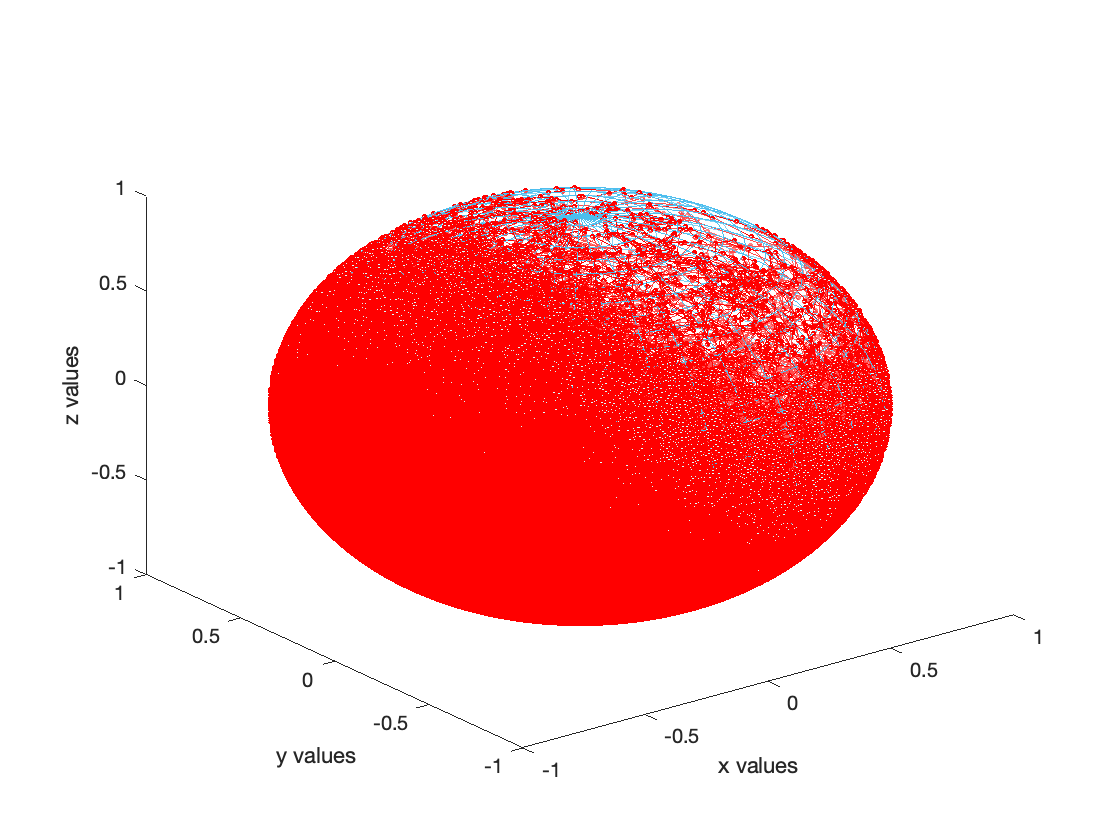

samples=load("MH_sphereDraws.mat");
xs=real(samples.samples(1,:))';
ys=real(samples.samples(2,:))';
zs=real(samples.samples(3,:))';
dim=size(xs);
plot3(xs,ys,zs,'-o','Color','r','MarkerSize',2,'MarkerFaceColor','#D9FFFF')
hold on
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*sin(phi).*cos(theta);
y=rho*sin(phi).*sin(theta);
z=rho*(cos(phi)+z_shift);
mesh(x,y,z,'EdgeColor',[0.3010 0.7450 0.9330],'FaceAlpha',.3)
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
hold off

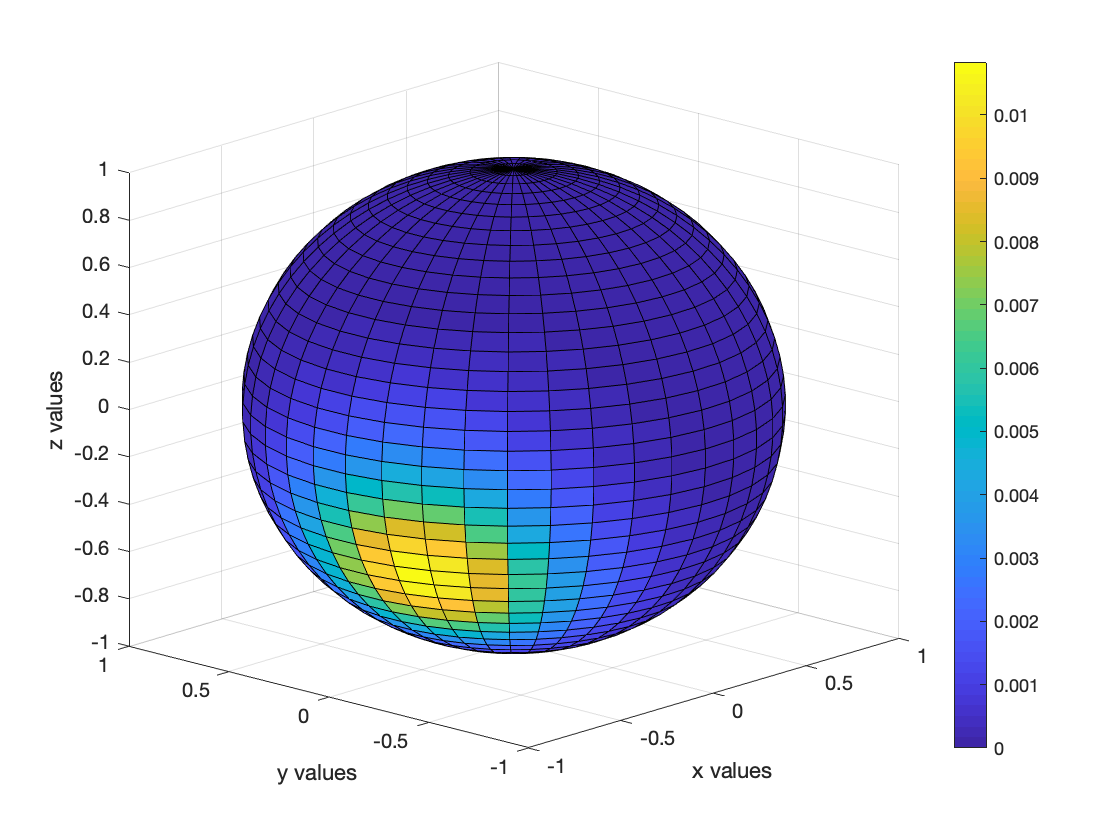

thetas_unshifted=atan(ys./xs);
theta_draws=thetas_unshifted+pi*(xs<0)+...
    2*pi*(xs>0&ys<0);
theta_draws(isnan(theta_draws))=0;
phi_draws=acos(zs-z_shift);

[n,d]=size(theta);
dens2=zeros(n,d);
for t=2:n
    for p=2:d
        x_in= (theta_draws>=theta(p,t-1))&(theta_draws<theta(p,t));
        y_in= (phi_draws>=phi(p-1,t))&(phi_draws<phi(p,t));
        dens2(p,t)=mean(x_in&y_in)*sin(phi(p-1,t-1));
    end
end
s2=surf(x,y,z);
s2.CData=dens2;
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
colorbar
view([-47.19 17.56])

% h = colorbar;
% set(h, 'ylim', [0 0.45])
% hold on
% % plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
% hold off